newData = readmatrix("2d_structured_200x20_016ms.csv");
newData = rmmissing(newData);
[x,ix,iix] = unique(newData(:,1))

x =          0
    0.0025
    0.0051
    0.0076
    0.0102
    0.0127
    0.0152
    0.0178
    0.0203
    0.0229


ix =         4379
         199
         198
         197
         196
         195
         194
         193
         192
         191


iix =    200
   199
   198
   197
   196
   195
   194
   193
   192
   191


[y,iy,iiy] = unique(newData(:,2))

y =          0
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026


iy =         4380
        4824
         199
         198
         197
         196
         195
         194
         193
         192


iiy =    201
   200
   199
   198
   197
   196
   195
   194
   193
   192


[z,iz,iiz] = unique(newData(:,3))

z = 	1.0e+-3 *

   -0.5000
    0.5000


iz =         4825
           1


iiz =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


%buddy = zeros(size(x,1),size(y,1),size(z,1))
xl = size(x,1)

xl = 201

yl = size(y,1)

yl = 4424

[P,iP,iiP] = unique(newData(:,4))

P =          0
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


iP =         4582
        4382
        4381
           1
        4180
         399
        3782
        4802
        4383
         598


iiP =      4
    38
    54
    78
   101
   125
   149
   173
   197
   221


% ix
% newData(ix,:)
% newData(ix(1),:)
% newData(iy,:)
% newData(iz,:)

% yope = newData(:,2) == y(1) & newData(:,1) == x(1) %& newData(:,3) == z(1)
% x2 = newData(:,1)
% x2(yope)
% newData(yope,4)
% newData(yope,3)
% z(1)
% %buddy(201,1,1)

yope = newData(:,2) == y(2) & newData(:,1) == x(1) %& newData(:,3) == z(1)

yope = 9648×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


max(yope)

ans = logical
   1


newData(yope,4)

ans =     0.0664
    0.0664


y(2)

ans = 0.0026

sum(newData(yope,4))

ans = 0.1328

% dude = zeros(size(x,1),size(y,1),size(z,1))
% if newData(ix(1),3) == z(2,1)
%    dude(ix(1),2)
% end

buddy = NaN(size(x,1),size(y,1),size(z,1))

buddy = buddy(:,:,1) =

  Columns 1 through 1,666

   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN 

for k = 1:2
    for n = 1:(yl)
        for m = 1:(xl)
           yope = newData(:,2) == y(n) & newData(:,1) == x(m) & newData(:,3) == z(k);
            if newData(yope,4)
                buddy(m,n,k) = newData(yope,4);
            end
            
        end
    end
end
buddy

buddy = buddy(:,:,1) =

  Columns 1 through 999

    0.0707    0.0664       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

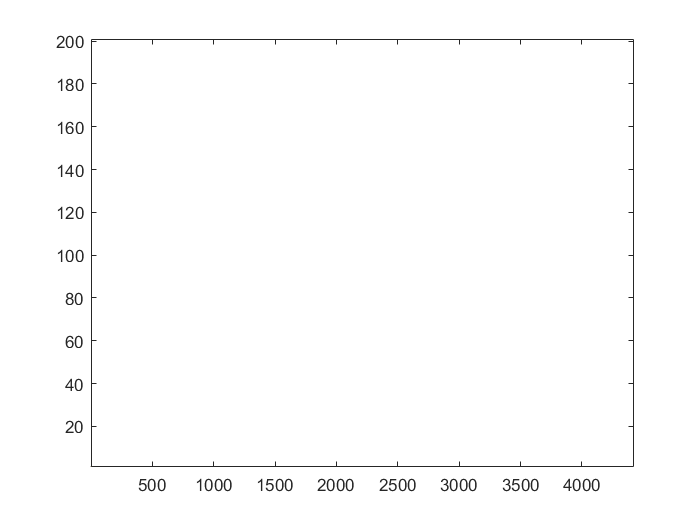

contourf(buddy(:,:,1))

buddy2 = NaN(size(x,1),size(y,1))

buddy2 =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

for n = 1:(xl)
    for m = 1:(yl)
        yope = newData(:,2) == y(m) & newData(:,1) == x(n); %& newData(:,3) == z(k);
        if newData(yope,4)
            buddy2(n,m) = max(newData(yope,4));
        end
            
    end
end
buddy2

buddy2 =     0.0707    0.0664       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0665       NaN    0.0635       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

max(buddy2(:,202:4424))

ans =        NaN    0.0600    0.0589    0.0564    0.0545    0.0529    0.0514    0.0498    0.0484    0.0469    0.0455    0.0440    0.0425    0.0410    0.0396    0.0382    0.0370    0.0359    0.0349    0.0341    0.0334    0.0328    0.0324    0.0320    0.0316    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0297    0.0295    0.0293    0.0291    0.0288    0.0286    0.0284    0.0281    0.0279    0.0276    0.0274    0.0272    0.0269    0.0267    0.0264    0.0262    0.0259


checker = newData(:,3)>0

checker = 9648×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Data2 = newData(checker,:)

Data2 =     0.5055    0.0026    0.0005    0.0001    0.0042    0.0041    0.0000    0.0000         0    0.5055    0.0026    0.0005
    0.5029    0.0026    0.0005    0.0003    0.0042    0.0041    0.0000    0.0000         0    0.5029    0.0026    0.0005
    0.5004    0.0026    0.0005    0.0004    0.0042    0.0041    0.0000    0.0000         0    0.5004    0.0026    0.0005
    0.4978    0.0026    0.0005    0.0005    0.0042    0.0041    0.0000    0.0000         0    0.4978    0.0026    0.0005
    0.4953    0.0026    0.0005    0.0007    0.0042    0.0041    0.0000    0.0000         0    0.4953    0.0026    0.0005
    0.4928    0.0026    0.0005    0.0008    0.0042    0.0041    0.0000    0.0000         0    0.4928    0.0026    0.0005
    0.4902    0.0026    0.0005    0.0009    0.0042    0.0042    0.0000    0.0000         0    0.4902    0.0026    0.0005
    0.4877    0.0026    0.0005    0.0010    0.0043    0.0042    0.0000    0.0000         0    0.4877    0.0026    0.0005
    0.4851    0.0026    

x2 = Data2(:,1)

x2 =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


y2= Data2(:,2)

y2 =     0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026


p2 = Data2(:,4)

p2 =     0.0001
    0.0003
    0.0004
    0.0005
    0.0007
    0.0008
    0.0009
    0.0010
    0.0012
    0.0013


[M,I] = max(x2)

M = 0.5080

I = 4381

unique(x2)

ans =          0
    0.0025
    0.0051
    0.0076
    0.0102
    0.0127
    0.0152
    0.0178
    0.0203
    0.0229


unique(y2)

ans =          0
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026


x2

x2 =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


sum(x2)/size(x2,1)

ans = 0.2540

xr = ceil(x2/max(x2)*200+1)

xr =    201
   199
   198
   197
   196
   195
   194
   193
   192
   191


yr = ceil(y2/max(y2)*4823+1)

yr =    128
   128
   128
   128
   128
   128
   128
   128
   128
   128


yr4 = round(y2,4)

yr4 =     0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026


xr4 = round(x2,4)

xr4 =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


[y2r,i2y,yi] = unique(round(y2,4))

y2r =          0
    0.0026
    0.0055
    0.0089
    0.0130
    0.0131
    0.0178
    0.0179
    0.0227
    0.0228


i2y =         4380
           1
         200
         399
         755
         598
         820
         797
        1139
         996


yi =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


[x2r,i2x,xi] = unique(round(x2,4));

g = yr4 == y2(i2y(1)) & xr4 == x2(i2x(1))

g = 4824×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


sum(g)

ans = 1

p2(g)

ans = 0.0707

g = yr4 == round(y2((i2y(6))),4)

g = 4824×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


p2(g)

ans =     0.0001
    0.0003
    0.0004
    0.0005
    0.0007
    0.0008
    0.0009
    0.0011
    0.0012
    0.0013


xr4r = unique(xr4)

xr4r =          0
    0.0025
    0.0051
    0.0076
    0.0102
    0.0127
    0.0152
    0.0178
    0.0203
    0.0229


sum(g)

ans = 158

round(y2((i2y(34))),4)

ans = 0.1000

Pmap = NaN(size(i2x,1),size(i2y,1))

Pmap =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   Na

for n = 1:34
    %for m = 1:size(i2x,1)
        %g = yr4 == y2(i2y(n)) & xr4 == x2(i2x(m));
        g = yr4 == round(y2((i2y(n))),4);
        %if sum(g)
            Pmap(:,n) = p2(g);
        %end
    %end
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

Pmap

Pmap

Pmap =     0.0707    0.0001    0.0001    0.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0000    0.0003    0.0003    0.0003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0665    0.0004    0.0004    0.0004       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

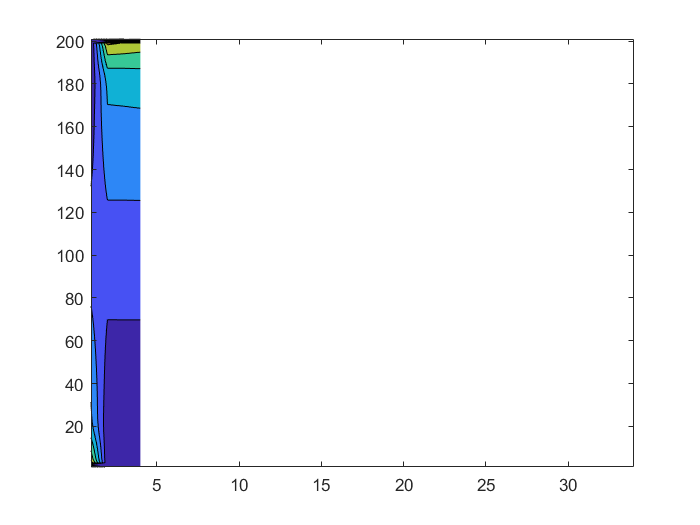

contourf(Pmap)

[C,ix2,ic] = unique(x2);
[D,iy2,id] = unique(y2);
MapDude = NaN(4824,4824);
ic(1)

ans = 200

Data2(ic(1),4)

ans = 1.2898e-04

% for n = 1:4824
%     for m = 1:4824
%         MapDude(n,m) = C(ic(n))==D(id(m))
%     end
% end

Data2(:,1)

ans =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


MapDude = NaN(201,4824)

MapDude =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   

% for n = 1:4824
%     for m = 1:201
%         MapDude(m,n) = Data2(m);
%     end
% end

yup = Data2(xr(1),1)

yup = 0.5029

x2(xr(1))

ans = 0.5029

yose = Data2(:,1) == x2(xr(1))

yose = 4824×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


sum(yose)

ans = 24

y2(1)

ans = 0.0026

Data2(:,2) == y2(yr(1))

ans = 4824×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


yes = NaN(size(xr,1),size(yr,1))

yes =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN 

for n=1:xl
    for m=1:yl
        
        yes(xr(n),yr(m)) = p2(n);
    end
end
yes

yes =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   

ans = NaN

sum(xr==0)

ans = 0

size(unique(x2),1)

ans = 201

zeros(1,size(unique(x2),1))

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(y2 == y2(yr(126)))

ans = 1

unique(yr)

ans =      1
   127
   128
   265
   431
   432
   630
   631
   632
   633


size(y2,1)

ans = 4824

g = zeros(size(y2,1),1)

g =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for n=1:size(y2,1)
    g(n) = x2(n)
end

g =     0.5055
         0
         0
         0
         0
         0
         0
         0
         0
         0


g =     0.5055
    0.5029
         0
         0
         0
         0
         0
         0
         0
         0


g =     0.5055
    0.5029
    0.5004
         0
         0
         0
         0
         0
         0
         0


g =     0.5055
    0.5029
    0.5004
    0.4978
         0
         0
         0
         0
         0
         0


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
         0
         0
         0
         0
         0


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
         0
         0
         0
         0


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
         0
         0
         0


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
         0
         0


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
         0


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g =     0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


g = 4824×1
    0.5055
    0.5029
    0.5004
    0.4978
    0.4953
    0.4928
    0.4902
    0.4877
    0.4851
    0.4826


unique(xr)
unique(yr)